# Fit thermal measurements

This live script is meant to fit the profiles of potential temperature and humidity measured in flight. It computes average profiles from the measurements you provide and fits them with a two term fouries series. You can play with the coefficients of the fourier series manually as your heart desires.

## Load your .csv files

This loads the data from each .csv file from Hardt (corresponding to one flight) into cell arrays that contain tables with the measured data. Upwind (UW), downwind (DW) and crosswind (CW) flights each go into a separate array. Additionally, all flights go into the "tables" array. When you start to get new measuments, you will have to change the code below to reflect how your files are named or structured!

The tables should have three colums: 

- relative distance: the distance to the center of the thermal, normalized such that -1 and 1 are at its outer diameter (defined in Hardt)

- ptemp_diff: the potential temperature difference at each position

- spec_hum_diff: the specific humidity difference at each position

% load all .csv files in the folder "C:\Users\Pedro\Documents\Faculdade\Bachelorarbeit\Hardt data" into a cell array
files = dir("C:\Users\Pedro\Documents\Faculdade\Bachelorarbeit\Hardt data\*.csv");

tablesUW = cell(length(files), 1);
tablesCW = cell(length(files), 1);
tablesDW = cell(length(files), 1);
tables = cell(length(files), 1);

for i = 1:length(files)
    tables{i} = import_thermal2(fullfile(files(i).folder, files(i).name), [17, Inf]);
    % check if file is crosswind (CW), downwind (DW) or upwind (UW) by checking the file name and store in the corresponding cell array
    if contains(files(i).name, "CW")
        tablesCW{i} = tables{i};
    elseif contains(files(i).name, "UW")
        tablesUW{i} = tables{i};
    elseif contains(files(i).name, "DW")
        tablesDW{i} = tables{i};
    else
        error("File name does not contain 'CW', 'DW' or 'UW'");
    end
end

% drop empty rows
tables = tables(~cellfun('isempty', tables));
tablesUW = tablesUW(~cellfun('isempty', tablesUW));
tablesCW = tablesCW(~cellfun('isempty', tablesCW));
tablesDW = tablesDW(~cellfun('isempty', tablesDW));

## Average profiles

Now we obtain the average profiles of ptemp and spec_hum. The profiles are truncated to -4 and 4 relative distance.

% compute average values for each flight type

[ptemp_DW_avg, spec_hum_DW_avg, rel_distDW] = average_hardt(tablesDW);
[ptemp_CW_avg, spec_hum_CW_avg, rel_distCW] = average_hardt(tablesCW);
[ptemp_UW_avg, spec_hum_UW_avg, rel_distUW] = average_hardt(tablesUW);
[ptemp_avg, spec_hum_avg, rel_dist] = average_hardt(tables);

## Fit profiles

Fit the profiles to a fourier series with two terms.

ptemp_DW_fit = fit(rel_distDW', ptemp_DW_avg', 'fourier2');
spec_hum_DW_fit = fit(rel_distDW', spec_hum_DW_avg', 'fourier2');

ptemp_CW_fit = fit(rel_distCW', ptemp_CW_avg', 'fourier2');
spec_hum_CW_fit = fit(rel_distCW', spec_hum_CW_avg', 'fourier2');

ptemp_UW_fit = fit(rel_distUW', ptemp_UW_avg', 'fourier2');
spec_hum_UW_fit = fit(rel_distUW', spec_hum_UW_avg', 'fourier2');

ptemp_fit = fit(rel_dist', ptemp_avg', 'fourier2');
spec_hum_fit = fit(rel_dist', spec_hum_avg', 'fourier2');

Plot the profiles and their fits.

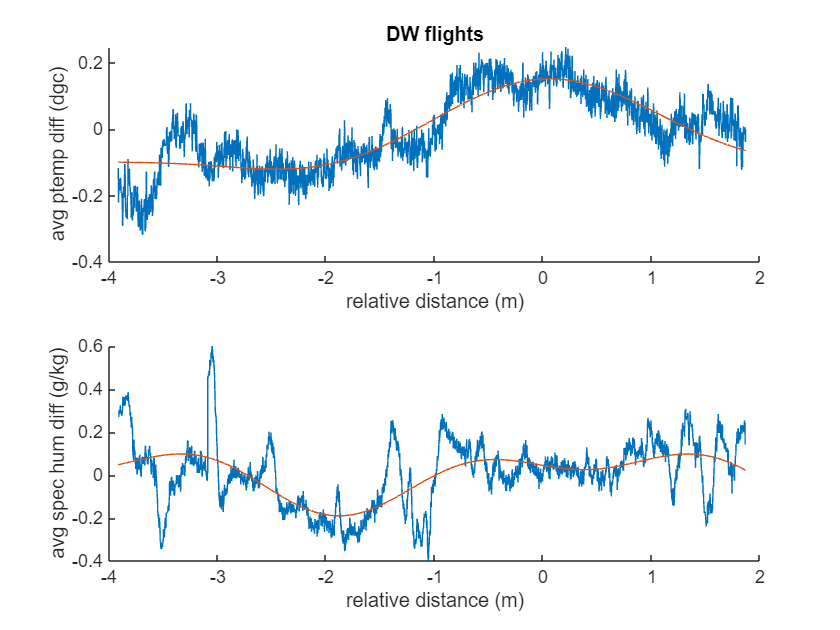

figure
subplot(2,1,1)
hold on
plot(rel_distDW, ptemp_DW_avg)
plot(rel_distDW, ptemp_DW_fit(rel_distDW))
xlabel('relative distance (m)')
ylabel('avg ptemp diff (dgc)')
title('DW flights')
subplot(2,1,2)
hold on
plot(rel_distDW, spec_hum_DW_avg)
plot(rel_distDW, spec_hum_DW_fit(rel_distDW))
xlabel('relative distance (m)')
ylabel('avg spec hum diff (g/kg)')

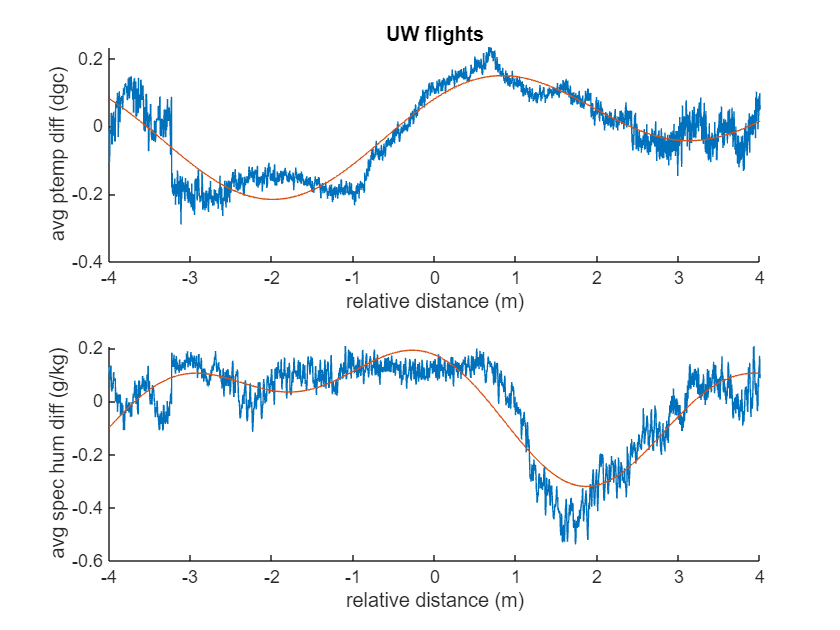


figure
subplot(2,1,1)
hold on
plot(rel_distUW, ptemp_UW_avg)
plot(rel_distUW, ptemp_UW_fit(rel_distUW))
xlabel('relative distance (m)')
ylabel('avg ptemp diff (dgc)')
title('UW flights')
subplot(2,1,2)
hold on
plot(rel_distUW, spec_hum_UW_avg)
plot(rel_distUW, spec_hum_UW_fit(rel_distUW))
xlabel('relative distance (m)')
ylabel('avg spec hum diff (g/kg)')

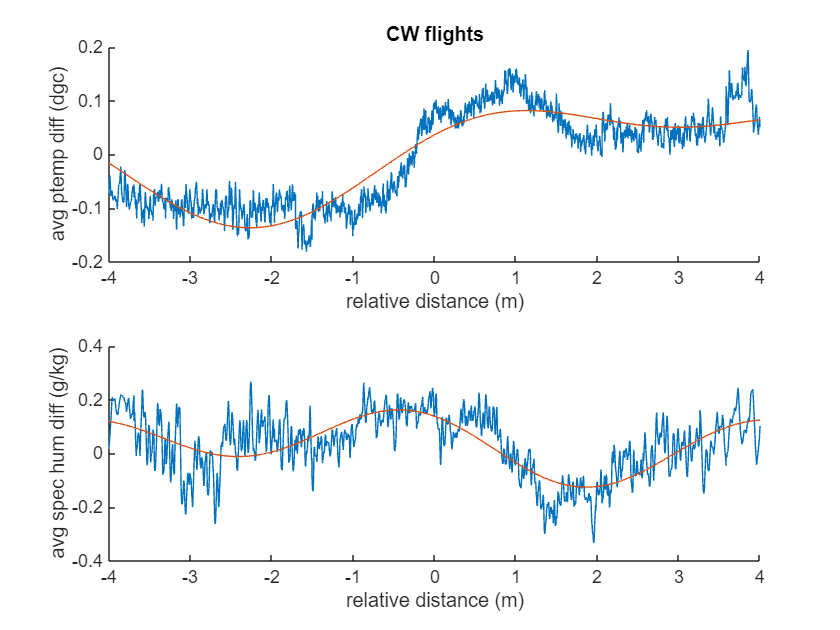


figure
subplot(2,1,1)
hold on
plot(rel_distCW, ptemp_CW_avg)
plot(rel_distCW, ptemp_CW_fit(rel_distCW))
xlabel('relative distance (m)')
ylabel('avg ptemp diff (dgc)')
title('CW flights')
subplot(2,1,2)
hold on
plot(rel_distCW, spec_hum_CW_avg)
plot(rel_distCW, spec_hum_CW_fit(rel_distCW))
xlabel('relative distance (m)')
ylabel('avg spec hum diff (g/kg)')

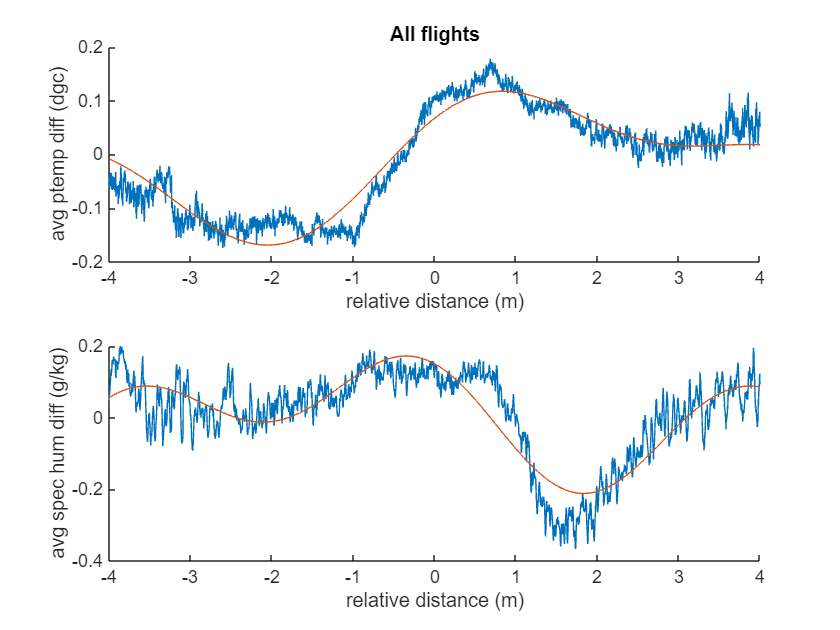


figure
subplot(2,1,1)
hold on
plot(rel_dist, ptemp_avg)
plot(rel_dist, ptemp_fit(rel_dist))
xlabel('relative distance (m)')
ylabel('avg ptemp diff (dgc)')
title('All flights')
subplot(2,1,2)
hold on
plot(rel_dist, spec_hum_avg)
plot(rel_dist, spec_hum_fit(rel_dist))
xlabel('relative distance (m)')
ylabel('avg spec hum diff (g/kg)')

## Change fit coefficients

If you wish to change the coeeficients of the fit manually, you can test out new values here.

% Original values
fit = spec_hum_DW_fit;
data = spec_hum_DW_avg;
coeff = coeffvalues(fit);
coeff_names = coeffnames(fit);
f = fittype(fit);

% New fourier series coefficients
a0 = -0.0358;
a1 = 0.1216;
b1 = 0.0955;
a2 = -0.0528;
b2 = -0.12; % changed this one
w = 1.1626;

new_fit = cfit(f,a0,a1,b1,a2,b2,w);

disp(f);

     General model Fourier2:
     f(a0,a1,b1,a2,b2,w,x) =  a0 + a1*cos(x*w) + b1*sin(x*w) + 
               a2*cos(2*x*w) + b2*sin(2*x*w)



fprintf('Original coefficients: %s\nNew coefficients:      %s', num2str(coeff), num2str([a0,a1,b1,a2,b2,w]))

Original coefficients: -0.0078252    0.082545    0.070649   -0.029496   -0.067557      1.3446
New coefficients:      -0.0358      0.1216      0.0955     -0.0528       -0.12      1.1626

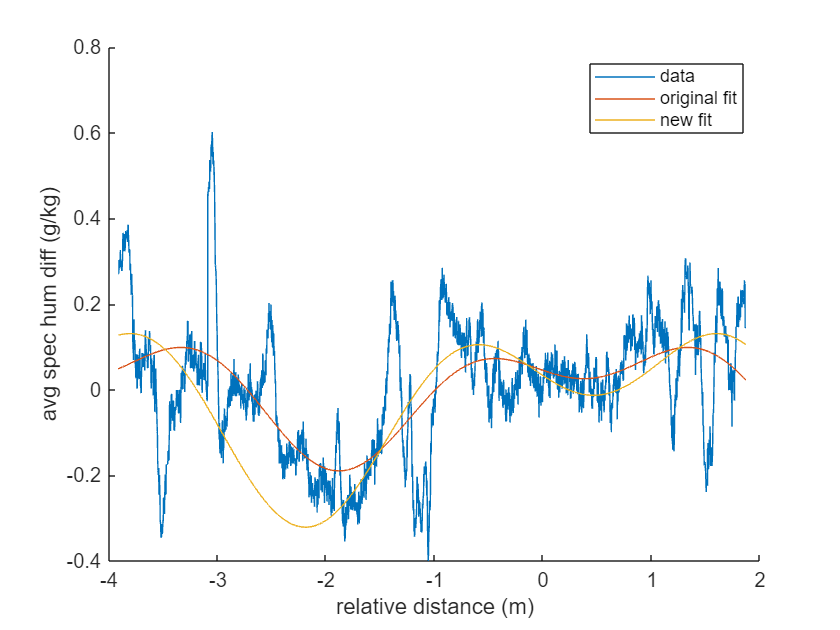

% Plot
figure
hold on
plot(rel_distDW, data, DisplayName='data')
plot(rel_distDW, fit(rel_distDW), DisplayName='original fit')
plot(rel_distDW, new_fit(rel_distDW),DisplayName='new fit')
xlabel('relative distance (m)')
ylabel('avg spec hum diff (g/kg)')
legend()

## Save coefficients to workspace

coeff_cw = [coeffvalues(ptemp_CW_fit);coeffvalues(spec_hum_CW_fit)];
coeff_uw = [coeffvalues(ptemp_UW_fit);coeffvalues(spec_hum_UW_fit)];
save("coeff_cw.mat","coeff_cw");
save("coeff_uw.mat","coeff_uw");
